clc
clear
x=[4,8,4,6,8,6,7,7,7,8,10,9,7,6,10,8,5,9,6,3,7,6,4,7,6,9,7,4,7,6,8,8,9,11,8,7,10,8,5,7,7,6,5,10,8,9,7,5,6,6,8,8,9,11,8,7,10,8];
xor=sort(x)

xor =      3     4     4     4     4     5     5     5     5     6     6     6     6     6     6     6     6     6     6     7     7     7     7     7     7     7     7     7     7     7     7     7     8     8     8     8     8     8     8     8     8     8     8     8     8     9     9     9     9     9


n=length(x)

n = 58

min(x)

ans = 3

max(x)

ans = 11

xmedia=mean(x)

xmedia = 7.2414

xmediana=median(xor)

xmediana = 7

xmoda=mode(x)

xmoda = 7


rango=range(x)

rango = 8

varianza=var(x)

varianza = 3.3091

desviacion=std(x)

desviacion = 1.8191


K=5

K = 5

l=rango/K

l = 1.6000

L=ceil(l)

L = 2


m1=4;
m=[m1 m1+L m1+(2*L) m1+(3*L) m1+(4*L)]

m =      4     6     8    10    12


marca=m';

intervalo=[3:2:13];
h=histogram(x,intervalo)

h =   Histogram with properties:

             Data: [4 8 4 6 8 6 7 7 7 8 10 9 7 6 10 8 5 9 6 3 7 6 4 7 6 9 7 4 7 6 8 8 9 11 8 7 10 8 5 7 7 6 5 10 8 9 7 5 6 6 8 8 9 11 8 7 10 8]
           Values: [5 14 26 11 2]
          NumBins: 5
         BinEdges: [3 5 7 9 11 13]
         BinWidth: 2
        BinLimits: [3 13]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


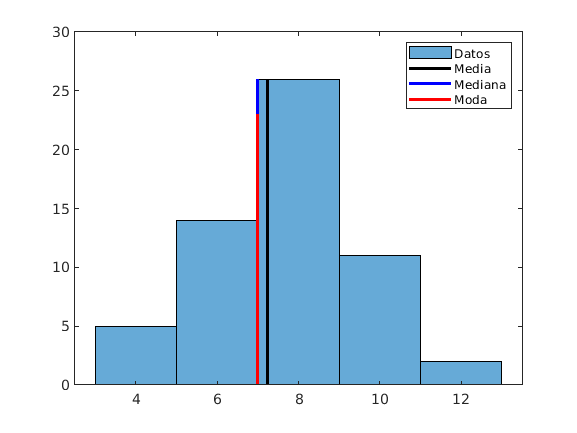

frecuencia=h.Values;
hold on
plot([xmedia xmedia],[0 26],'black','LineWidth',2)
plot([xmediana xmediana],[0 26],'b','LineWidth',2)
plot([xmoda xmoda],[0 23],'r','LineWidth',2)
legend('Datos','Media', 'Mediana','Moda')  
hold off


fa=frecuencia';
fr=fa/n;
F=cumsum(fa);
Fr=F/n;
table(marca,fa,fr,F,Fr)

ans = 5×5 table
    marca    fa       fr       F        Fr   
    _____    __    ________    __    ________

      4       5    0.086207     5    0.086207
      6      14     0.24138    19     0.32759
      8      26     0.44828    45     0.77586
     10      11     0.18966    56     0.96552
     12       2    0.034483    58           1


h =   Histogram with properties:

             Data: [4 8 4 6 8 6 7 7 7 8 10 9 7 6 10 8 5 9 6 3 7 6 4 7 6 9 7 4 7 6 8 8 9 11 8 7 10 8 5 7 7 6 5 10 8 9 7 5 6 6 8 8 9 11 8 7 10 8]
           Values: [5 14 26 11 2]
          NumBins: 5
         BinEdges: [3 5 7 9 11 13]
         BinWidth: 2
        BinLimits: [3 13]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


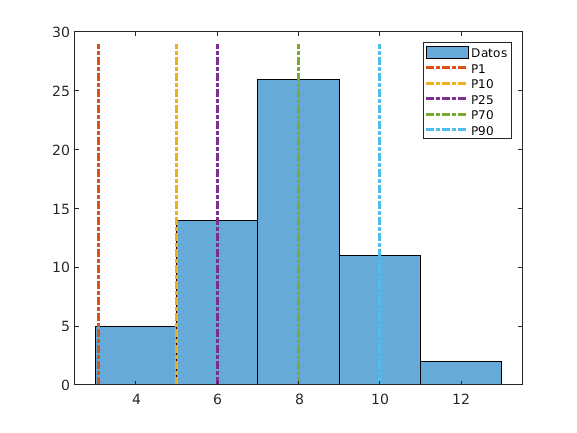


p1=prctile(x,1);

p10=prctile(x,10);
p25=prctile(x,25);
p70=prctile(x,70);
p90=prctile(x,90);
intervalo=[3:2:13];
h=histogram(x,intervalo)
hold on
plot([p1 p1],[0 29],'-.','LineWidth',2)
plot([p10 p10],[0 29],'-.','LineWidth',2)
plot([p25 p25],[0 29],'-.','LineWidth',2)
plot([p70 p70],[0 29],'-.','LineWidth',2)
plot([p90 p90],[0 29],'-.','LineWidth',2)
legend('Datos','P1', 'P10','P25','P70','P90')  
hold off



d1=prctile(x,10);
d2=prctile(x,20);
d5=prctile(x,50);
d7=prctile(x,70);
intervalo=[3:2:13];
h=histogram(x,intervalo)

h =   Histogram with properties:

             Data: [4 8 4 6 8 6 7 7 7 8 10 9 7 6 10 8 5 9 6 3 7 6 4 7 6 9 7 4 7 6 8 8 9 11 8 7 10 8 5 7 7 6 5 10 8 9 7 5 6 6 8 8 9 11 8 7 10 8]
           Values: [5 14 26 11 2]
          NumBins: 5
         BinEdges: [3 5 7 9 11 13]
         BinWidth: 2
        BinLimits: [3 13]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


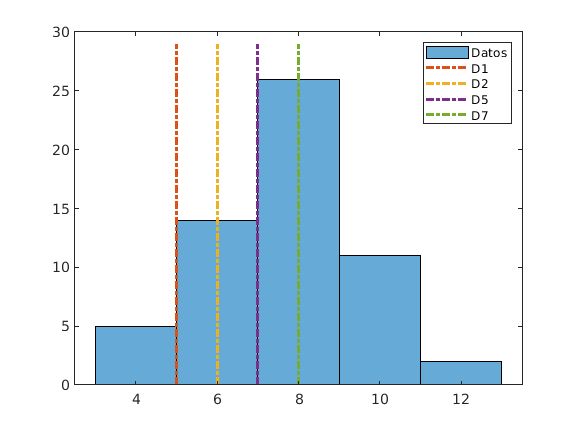

hold on
plot([d1 d1],[0 29],'-.','LineWidth',2)
plot([d2 d2],[0 29],'-.','LineWidth',2)
plot([d5 d5],[0 29],'-.','LineWidth',2)
plot([d7 d7],[0 29],'-.','LineWidth',2)
legend('Datos','D1', 'D2','D5','D7')  
hold off





q1=prctile(x,25);
q2=prctile(x,50);
q3=prctile(x,75);
intervalo=[3:2:13];
h=histogram(x,intervalo)

h =   Histogram with properties:

             Data: [4 8 4 6 8 6 7 7 7 8 10 9 7 6 10 8 5 9 6 3 7 6 4 7 6 9 7 4 7 6 8 8 9 11 8 7 10 8 5 7 7 6 5 10 8 9 7 5 6 6 8 8 9 11 8 7 10 8]
           Values: [5 14 26 11 2]
          NumBins: 5
         BinEdges: [3 5 7 9 11 13]
         BinWidth: 2
        BinLimits: [3 13]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


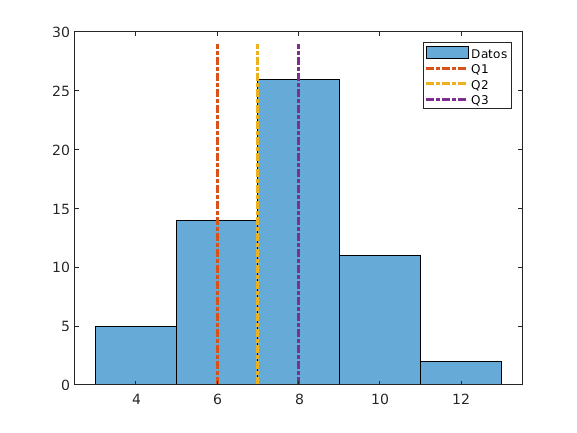

hold on
plot([q1 q1],[0 29],'-.','LineWidth',2)
plot([q2 q2],[0 29],'-.','LineWidth',2)
plot([q3 q3],[0 29],'-.','LineWidth',2)
legend('Datos','Q1', 'Q2','Q3')  
hold off

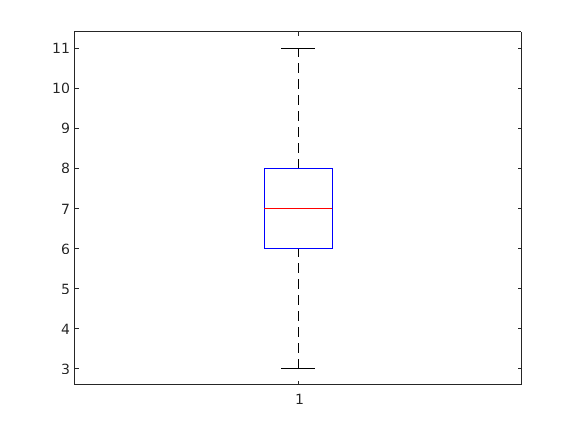


boxplot(xor);